im = x004

im = 570×760×3 uint8 array
im(:,:,1) =

     4     4     2     2     2     2     1     1     3     1     0     0     2     3     4     5    13    35    62    86   100   109   117   123   121   125   123   114   113   118   117   115   122   117   117   123   123   119   121   127   122   122   120   118   115   115   118   124   125   124   124   126   129   129   126   123   123   123   126   126   127   128   128   129   129   131   131   132   132   131   130   130   136   136   136   136   136   136   136   138   138   140   139   138   139   138   138   138   140   144   145   143   144   148   150   147   148   150   151   150   150   150   152   154   153   153   155   154   154   153   154   153   157   156   155   155   155   155   157   158   158   159   160   159   158   157   157   157   161   157   158   162   163   160   162   166   163   165   170   171   172   169   165   163   153   153   154   157   163   166   165   165   169   168   166   167   169   170   168   169


[X,inx] = ROI(im)

X = 570×760×3 uint8 array
X(:,:,1) =

     4     4     2     2     2     2     1     1     3     1     0     0     2     3     4     5    13    35    62    86   100   109   117   123   121   125   123   114   113   118   117   115   122   117   117   123   123   119   121   127   122   122   120   118   115   115   118   124   125   124   124   126   129   129   126   123   123   123   126   126   127   128   128   129   129   131   131   132   132   131   130   130   136   136   136   136   136   136   136   138   138   140   139   138   139   138   138   138   140   144   145   143   144   148   150   147   148   150   151   150   150   150   152   154   153   153   155   154   154   153   154   153   157   156   155   155   155   155   157   158   158   159   160   159   158   157   157   157   161   157   158   162   163   160   162   166   163   165   170   171   172   169   165   163   153   153   154   157   163   166   165   165   169   168   166   167   169   170   168   169  

inx =     27
    28
    29
    30
    31
    32
    33
    34
    35
    36


A = rgb2lab(X)

A = A(:,:,1) =

    0.2530    0.2530    0.1364    0.1364    0.1364    0.1364    0.2544    0.2544    0.7829    0.2544    0.1961    0.1961    0.3127    0.5671    0.8215    0.5272    1.1386    8.3715   20.9214   30.7937   36.0665   39.0071   41.0042   42.2276   40.8740   41.9303   40.3127   36.4127   36.0051   38.2961   38.7187   37.3255   38.7708   36.4722   36.4722   38.8865   38.8865   37.2789   38.0836   40.4864   37.9569   37.9569   37.1525   36.3463   35.1333   35.1333   36.3463   37.9570   37.0661   36.1546   35.8984   36.6962   37.8902   37.8902   36.6962   35.4990   35.4990   35.4990   35.9530   35.9530   36.3507   36.7480   36.7480   36.6376   36.1387   36.4348   36.4348   36.8275   36.8275   36.4348   36.0419   36.0419   38.1524   38.1524   38.1524   38.1524   38.1524   38.1524   38.1524   38.2173   37.7675   37.8503   37.4579   37.0713   37.2292   36.8434   36.3893   36.3893   36.7051   38.2326   38.1677   37.4077   37.9985   39.5201   39.6211   38.4867   39.5113   40.2711   4

mn = min(min(A))

mn = mn(:,:,1) =

     0


mn(:,:,2) =

  -81.1592


mn(:,:,3) =

   -5.7674


mx = max(max(A))

mx = mx(:,:,1) =

   85.2333


mx(:,:,2) =

   53.3766


mx(:,:,3) =

   78.9251


mx = mx(:)

mx =    85.2333
   53.3766
   78.9251


mn = mn(:)

mn =          0
  -81.1592
   -5.7674


LABp = A;
LABp(:,:,1) = (A(:,:,1)-mn(1))/(mx(1)-mn(1));
LABp(:,:,2) = (A(:,:,2)-mn(2))/(mx(2)-mn(2));
LABp(:,:,3) = (A(:,:,3)-mn(3))/(mx(3)-mn(3))

LABp = LABp(:,:,1) =

    0.0030    0.0030    0.0016    0.0016    0.0016    0.0016    0.0030    0.0030    0.0092    0.0030    0.0023    0.0023    0.0037    0.0067    0.0096    0.0062    0.0134    0.0982    0.2455    0.3613    0.4232    0.4577    0.4811    0.4954    0.4796    0.4919    0.4730    0.4272    0.4224    0.4493    0.4543    0.4379    0.4549    0.4279    0.4279    0.4562    0.4562    0.4374    0.4468    0.4750    0.4453    0.4453    0.4359    0.4264    0.4122    0.4122    0.4264    0.4453    0.4349    0.4242    0.4212    0.4305    0.4445    0.4445    0.4305    0.4165    0.4165    0.4165    0.4218    0.4218    0.4265    0.4311    0.4311    0.4299    0.4240    0.4275    0.4275    0.4321    0.4321    0.4275    0.4229    0.4229    0.4476    0.4476    0.4476    0.4476    0.4476    0.4476    0.4476    0.4484    0.4431    0.4441    0.4395    0.4349    0.4368    0.4323    0.4269    0.4269    0.4306    0.4486    0.4478    0.4389    0.4458    0.4637    0.4649    0.4515    0.4636    0.47

Z = LABp;
Z(:,:,1) = adapthisteq(LABp(:,:,1),'NumTiles',[8 8],'ClipLimit',0.005);
Z(:,:,2) = adapthisteq(LABp(:,:,2),'NumTiles',[8 8],'ClipLimit',0.005);
Z(:,:,3) = adapthisteq(LABp(:,:,3),'NumTiles',[8 8],'ClipLimit',0.005)

Z = Z(:,:,1) =

    0.0177    0.0177    0.0088    0.0088    0.0088    0.0088    0.0177    0.0177    0.0265    0.0177    0.0177    0.0177    0.0177    0.0265    0.0265    0.0265    0.0327    0.1113    0.2377    0.3391    0.4640    0.5434    0.5868    0.5985    0.5823    0.5948    0.5773    0.4728    0.4640    0.5258    0.5346    0.4993    0.5346    0.4728    0.4728    0.5346    0.5346    0.4993    0.5169    0.5773    0.5169    0.5169    0.4905    0.4728    0.4375    0.4363    0.4701    0.5125    0.4847    0.4574    0.4475    0.4717    0.4964    0.4949    0.4675    0.4330    0.4317    0.4305    0.4454    0.4441    0.4509    0.4576    0.4562    0.4547    0.4375    0.4441    0.4427    0.4491    0.4477    0.4386    0.4295    0.4282    0.4760    0.4745    0.4730    0.4716    0.4701    0.4686    0.4672    0.4657    0.4554    0.4540    0.4437    0.4340    0.4326    0.4236    0.4153    0.4140    0.4194    0.4511    0.4496    0.4305    0.4467    0.4805    0.4879    0.4511    0.4761    0.4923    

LABp(:,:,1) = Z(:,:,1)*(mx(1)-mn(1)) + mn(1);
LABp(:,:,2) = Z(:,:,2)*(mx(2)-mn(2)) + mn(2);
LABp(:,:,3) = Z(:,:,3)*(mx(3)-mn(3)) + mn(3)

LABp = LABp(:,:,1) =

    1.5044    1.5044    0.7522    0.7522    0.7522    0.7522    1.5044    1.5044    2.2566    1.5044    1.5044    1.5044    1.5044    2.2566    2.2566    2.2566    2.7869    9.4827   20.2602   28.9043   39.5462   46.3160   50.0154   51.0142   49.6331   50.6936   49.2015   40.2984   39.5462   44.8116   45.5638   42.5550   45.5638   40.2984   40.2984   45.5638   45.5638   42.5550   44.0594   49.2015   44.0594   44.0594   41.8028   40.2984   37.2896   37.1912   40.0651   43.6852   41.3095   38.9816   38.1427   40.2063   42.3094   42.1847   39.8444   36.9029   36.7994   36.6959   37.9655   37.8526   38.4323   39.0001   38.8795   38.7589   37.2880   37.8491   37.7325   38.2764   38.1558   37.3826   36.6106   36.4977   40.5671   40.4424   40.3176   40.1929   40.0682   39.9435   39.8187   39.6940   38.8171   38.6924   37.8154   36.9936   36.8703   36.1054   35.3998   35.2832   35.7435   38.4468   38.3220   36.6929   38.0726   40.9567   41.5842   38.4506   40.5825   41.96

%BrightRange = [68.19, 132.81, 92.37];
BrightRange = [32.3438, 65.8206, 10.0466]

BrightRange =    32.3438   65.8206   10.0466


Brightness = [51.4732   34.5079   51.0550]

Brightness =    51.4732   34.5079   51.0550


[R, C, nBands] = size(X)

R = 570

C = 760

nBands = 3

npixels = R * C

npixels = 433200

A = reshape(LABp,[npixels nBands])

A =     1.5044  -26.5819    0.2488
    1.5044  -26.5819    0.2488
    0.7522  -27.7692    0.2488
    0.7522  -27.7692    0.2488
    1.5044  -28.9565    1.7437
    1.5044  -30.1438    1.7437
    1.5044  -31.3311    1.7437
    1.5044  -31.3311    1.7437
    1.5044  -31.3311    1.7437
    1.5044  -31.3311    1.7437


B = A(inx,:)

B =    12.0969  -13.3852   13.9599
   20.5561  -17.6479   19.1552
   27.6096  -18.8157   21.1279
   36.5374  -22.0467   23.8480
   42.5550  -22.8058   25.0366
   46.3160  -21.1125   28.4306
   47.0682  -16.7525   34.5939
   47.8204  -14.5725   40.4018
   44.8003  -12.2266   38.8535
   42.5324  -12.2552   38.8001


muVec = mean(B,1)        % Vector of mean in each band

muVec =    46.1314   29.1260   50.1325


sdx = std(B,0,1)

sdx =     8.2551   10.0323    7.4737


scaleA = BrightRange./(7.5*sdx)

scaleA =     0.5224    0.8748    0.1792


offset = Brightness - scaleA.*muVec

offset =    27.3738    9.0290   42.0695


B = bsxfun(@plus, B*diag(scaleA), offset)

B =    33.6934   -2.6802   44.5716
   38.1125   -6.4091   45.5028
   41.7973   -7.4307   45.8564
   46.4612  -10.2571   46.3439
   49.6049  -10.9212   46.5569
   51.5696   -9.4399   47.1653
   51.9626   -5.6258   48.2699
   52.3556   -3.7188   49.3109
   50.7778   -1.6666   49.0334
   49.5931   -1.6917   49.0238


A(inx, :) = B;  
LABp = reshape(A, [R C nBands])

LABp = LABp(:,:,1) =

    1.5044    1.5044    0.7522    0.7522    0.7522    0.7522    1.5044    1.5044    2.2566    1.5044    1.5044    1.5044    1.5044    2.2566    2.2566    2.2566    2.7869    9.4827   37.9579   42.4737   48.0330   51.5696   53.5022   54.0240   53.3025   53.8565   53.0771   48.4260   48.0330   50.7837   51.1767   49.6049   51.1767   48.4260   48.4260   51.1767   51.1767   49.6049   50.3908   53.0771   50.3908   50.3908   49.2119   48.4260   46.8542   46.8028   48.3041   50.1953   48.9542   47.7381   47.2999   48.3779   49.4766   49.4114   48.1889   46.6522   46.5981   46.5440   47.2073   47.1483   47.4511   47.7478   47.6848   47.6218   46.8534   47.1465   47.0855   47.3697   47.3067   46.9028   46.4995   46.4405   48.5664   48.5012   48.4361   48.3709   48.3057   48.2406   48.1754   48.1103   47.6522   47.5870   47.1289   46.6996   46.6351   46.2355   45.8669   45.8060   46.0465   47.4587   47.3935   46.5425   47.2632   48.7699   49.0977   47.4607   48.5744   49.29

Z = lab2rgb(LABp)

Z = Z(:,:,1) =

   -0.1485   -0.1485   -0.1561   -0.1561   -0.1561   -0.1561   -0.1544   -0.1544   -0.1538   -0.1544   -0.1594   -0.1594   -0.1544   -0.1498   -0.1490   -0.1448   -0.1216    0.0253    0.3783    0.4014    0.4440    0.4756    0.5087    0.5275    0.5326    0.5505    0.5640    0.5253    0.5211    0.5392    0.5277    0.5210    0.5681    0.5441    0.5441    0.5685    0.5685    0.5571    0.5657    0.5893    0.5772    0.5772    0.5641    0.5612    0.5439    0.5437    0.5605    0.5930    0.6053    0.6075    0.6077    0.6147    0.6271    0.6263    0.6124    0.6000    0.5993    0.5986    0.6204    0.6196    0.6180    0.6213    0.6204    0.6290    0.6294    0.6405    0.6395    0.6424    0.6413    0.6363    0.6313    0.6302    0.6544    0.6533    0.6522    0.6511    0.6500    0.6489    0.6478    0.6590    0.6611    0.6717    0.6658    0.6602    0.6627    0.6574    0.6605    0.6591    0.6699    0.6816    0.6896    0.6787    0.6815    0.6944    0.7121    0.6920    0.6900    0.6935    

test = reshape(Z,[],3)

test =    -0.1485    0.0857    0.0145
   -0.1485    0.0857    0.0145
   -0.1561    0.0816    0.0035
   -0.1561    0.0816    0.0035
   -0.1544    0.0895   -0.0002
   -0.1583    0.0915   -0.0004
   -0.1621    0.0934   -0.0006
   -0.1621    0.0934   -0.0006
   -0.1621    0.0934   -0.0006
   -0.1621    0.0934   -0.0006


mean(uint8(test(inx,:) * 255))

ans =   191.9198   95.5194   31.9018


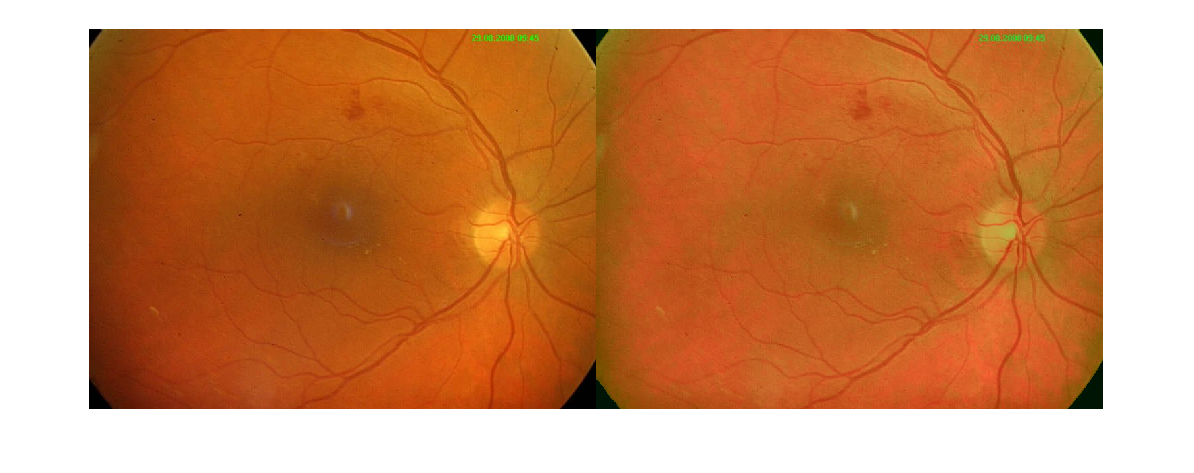

figure, imshowpair(X, Z, 'montage')

Z = uint8(Z * 255);

mqssim = qssim(Z, im)

mqssim = 0.9690